clear 
close all
clc

ampl_value = 5;
rot_nonrot_value = 'rot';
rot_nonrot_value = string(rot_nonrot_value);
% Define the base directory for input and output files
input_dir = sprintf('D:\\Matlab\\Matlab input\\20240805_full_plate\\20240805_%s_2.6Hz_%smm_full_plate_separate_frames\\Results\\',rot_nonrot_value,string(ampl_value));
output_dir = sprintf('D:\\Matlab\\Matlab output\\20240805_full_plate_results\\20240805_%s_2.6Hz_%smm_full_plate\\FFT\\',rot_nonrot_value,string(ampl_value));

% Define the base file name and extension
base_file_name = sprintf('20240805_%s_2.6Hz_%smm_full_plate_frame_',rot_nonrot_value,string(ampl_value));
file_extension = 'A_vel_new.dat';

frame_num = 190;
% Construct the file name
frame_str = sprintf('%04d', frame_num);
file_name = [base_file_name, frame_str, file_extension];
input_file = fullfile(input_dir, file_name);

% Load the data
dr = loadvec(input_file);

% Copy dr to dr_new & delete rows and columns with only zeros
dr_new = dr;
dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
dr_new.vy(all(dr_new.vy == 0, 2), :) = [];

% Compute the surface height
h_0 = 150; % surface-pattern distance in mm
h = surfheight(dr_new, h_0);
surface_height = h.w;


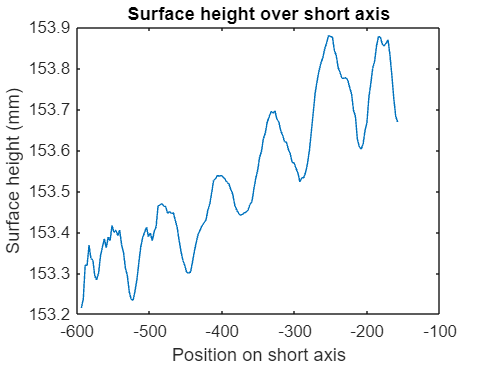

% Surface height on short axis
% Plot the amplitude/surface height over the short axis
surf_height_short_axis = surface_height(170,:);
ampl_short_axis = surf_height_short_axis - mean(surf_height_short_axis);
values_short_axis = h.y;
plot(values_short_axis,surf_height_short_axis)
title('Surface height over short axis')
xlabel('Position on short axis')
ylabel('Surface height (mm)')

output_file_png_surf_height_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_surf_height_short_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_surf_height_short);

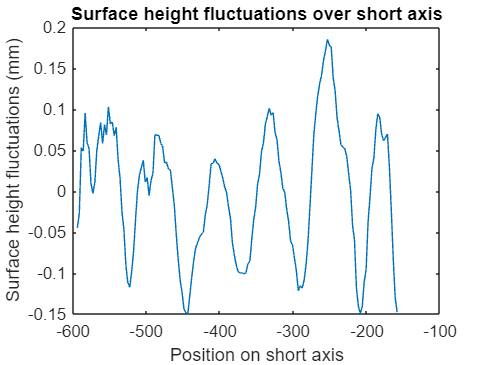

output_file_fig_surf_height_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_surf_height_short_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_surf_height_short);

% Fit a polynomial (e.g., a linear fit) to the surface height data
p_short_axis = polyfit(values_short_axis, surf_height_short_axis, 1);  % 1 for linear fit

% Calculate the fitted values
fitted_values_short_axis = polyval(p_short_axis, values_short_axis);

% Subtract the fitted values from the original data to obtain the fluctuations
fluctuations_short_axis = surf_height_short_axis - fitted_values_short_axis;

% Plot the fluctuations
figure;
plot(values_short_axis, fluctuations_short_axis);
title('Surface height fluctuations over short axis');
xlabel('Position on short axis');
ylabel('Surface height fluctuations (mm)');
output_file_png_fluc_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_fluc_short_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_fluc_short);

output_file_fig_fluc_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_fluc_short_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_fluc_short);

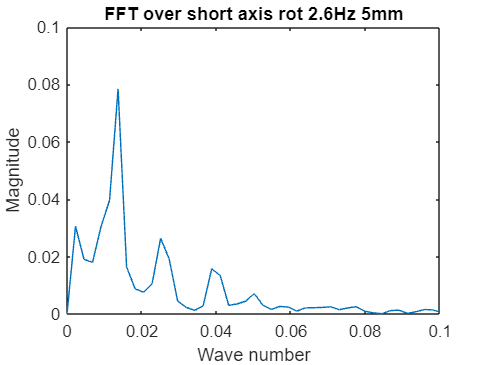


% plot(values_short_axis,ampl_short_axis)
% title('Amplitude over short axis')
% xlabel('Position on short axis')
% ylabel('Amplitude')


L_short_axis = length(fluctuations_short_axis);

% Compute Fourier transform and rewrite frequency

%Fourier over short axis
four_1d_short_axis = fft(fluctuations_short_axis);
distance_short_axis = h.y(2)-h.y(1); % Distance between two values
freq_short_axis = 1/distance_short_axis; % per meter
freq_four_short_axis = (0:length(four_1d_short_axis)-1)*freq_short_axis/length(four_1d_short_axis);

% Plot the Fourier transform against frequencies
plot(freq_four_short_axis,2*abs(four_1d_short_axis/L_short_axis))
xlabel('Wave number')
ylabel('Magnitude')
title(sprintf('FFT over short axis %s 2.6Hz %smm',rot_nonrot_value,string(ampl_value)))
xlim([0 0.1]);
ylim([0 0.1]);
output_file_png_fft_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_FFT_short_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_fft_short);

output_file_fig_fft_short = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_FFT_short_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_fft_short);

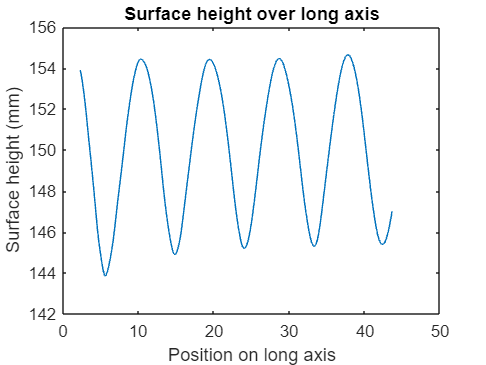

% Plot the amplitude/surface height over the long axis
%ampl = surface_height(30,:,2);
surf_height_long_axis = surface_height(:,30);
ampl_long_axis = surf_height_long_axis - mean(surf_height_long_axis);
%ampl = surface_height(30,40,:);
values_long_axis = h.x;
%values_time_axis = start_frame:1:end_frame;
plot(values_long_axis*0.036,surf_height_long_axis)
%plot(values_time_axis,ampl)
title('Surface height over long axis')
xlabel('Position on long axis')
ylabel('Surface height (mm)')
output_file_png_surf_height_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_surf_height_long_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_surf_height_long);

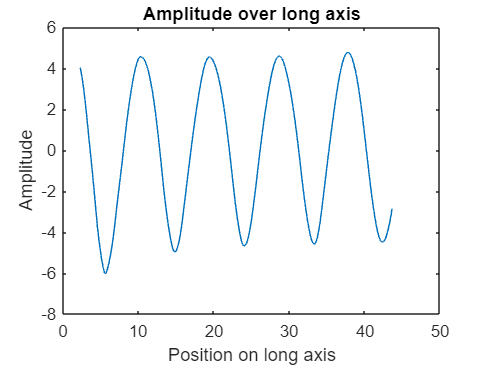

output_file_fig_surf_height_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_surf_height_long_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_surf_height_long);

L_long_axis = length(surf_height_long_axis);

plot(values_long_axis*0.036,ampl_long_axis)
title('Amplitude over long axis')
xlabel('Position on long axis')
ylabel('Amplitude')

output_file_png_ampl_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_ampl_long_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_ampl_long);

output_file_fig_ampl_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_ampl_long_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_ampl_long);


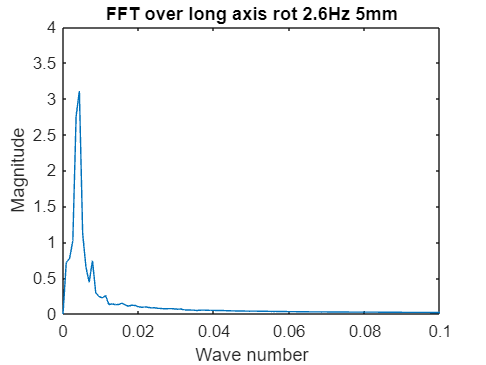

%Fourier over long axis
four_1d_long_axis = fft(ampl_long_axis);
distance = h.x(2)-h.x(1);
%distance = 1;
freq_long_axis = 1/distance;
freq_four_long_axis = (0:length(four_1d_long_axis)-1)*freq_long_axis/length(four_1d_long_axis);

% Plot the Fourier transform against frequencies
plot(freq_four_long_axis,2*abs(four_1d_long_axis/L_long_axis))
xlabel('Wave number')
ylabel('Magnitude')
title(sprintf('FFT over long axis %s 2.6Hz %smm',rot_nonrot_value,string(ampl_value)))
xlim([0 0.1]);
ylim([0 4]);
output_file_png_fft_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_FFT_long_axis_%s.png',rot_nonrot_value,string(ampl_value), string(frame_num)));
exportgraphics(gcf, output_file_png_fft_long);

output_file_fig_fft_long = fullfile(output_dir, sprintf('20240805_%s_2.6Hz_%smm_full_plate_FFT_long_axis_%s.fig',rot_nonrot_value,string(ampl_value), string(frame_num)));
savefig(gcf, output_file_fig_fft_long);

% % Performing a 2D Fourier transform on the surface heights 
% four_2d = fft2(surface_height(:,:)-mean(surface_height(:,:)));
% %plot(four_2d)
% imagesc(abs(fftshift(four_2d)));
% 
% xlim([70.0 100.0]);
% ylim([150 290]);

% % Tryout example
% % Create and plot a signal x
% Ts = 1/50;
% t = 0:Ts:10-Ts;
% x = sin(2*pi*15*t) + sin(2*pi*20*t);
% plot(t,x)
% xlabel('Time (seconds)')
% ylabel('Amplitude')
% L = length(t);
% 
% % Compute Fourier transform of x and formulate frequency f
% y = fft(x);
% fs = 1/Ts;
% f = (0:length(y)-1)*fs/length(y);
% 
% % Plot Fourier transform as function of frequency
% plot(f,2*abs(y/L))
% xlabel('Frequency (Hz)')
% ylabel('Magnitude')
% title('Magnitude')
% 
% % Shift Fourier transform to be symmetric around 0
% n = length(x);
% fshift = (-n/2:n/2-1)*(fs/n);
% yshift = fftshift(y);
% plot(fshift,abs(yshift))
% xlabel('Frequency (Hz)')
% ylabel('Magnitude')

% % Perform 3D Fourier Transform
% H = fftn(surface_height);
% 
% % Calculate the magnitude
% magnitude = abs(H);
% 
% % Define the range of frames to process
% start_frame = 160;
% end_frame = 164;
% nt = end_frame - start_frame;

% % Define the frequency axes
% [Nx, Ny, Nt] = size(H);
% fx = linspace(-Nx/2, Nx/2-1, Nx); % Spatial frequencies in x direction
% fy = linspace(-Ny/2, Ny/2-1, Ny); % Spatial frequencies in y direction
% ft = linspace(-Nt/2, Nt/2-1, Nt); % Temporal frequencies
% 
% % Shift the zero frequency component to the center of the spectrum
% magnitude_shifted = fftshift(magnitude);
% 
% % 3D surface plot for a specific temporal frequency slice
% timeIndex = round(Nt / 2); % Mid-point in the temporal frequency domain
% [X, Y] = meshgrid(fx, fy);
% figure;
% surf(transpose(X), transpose(Y), magnitude_shifted(:, :, timeIndex));
% title(['Magnitude of Fourier Transform at temporal frequency index ', num2str(timeIndex)]);
% xlabel('Spatial frequency in x direction');
% ylabel('Spatial frequency in y direction');
% zlabel('Magnitude');

% % To make a 3D matrix with all surface heights over space and time
% 
% % Load one file to get the dimensions
% file_name = [base_file_name, '0220', file_extension];
% input_file = fullfile(input_dir, file_name);
% dr = loadvec(input_file);
% % Copy dr to dr_new & delete rows and columns with only zeros
% dr_new = dr;
% dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
% dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
% dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
% dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
% dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
% dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
% h_0 = 150; % surface-pattern distance in mm
% h = surfheight(dr_new, h_0);
% 
% [nx, ny] = size(h.w);
% 
% surface_height_3d = zeros(nx, ny, nt);
% 
% for frame_num = start_frame:end_frame
%     frame_str = sprintf('%04d', frame_num);
%     file_name = [base_file_name, frame_str, file_extension];
%     input_file = fullfile(input_dir, file_name);
% 
%     % Load the data
%     dr = loadvec(input_file);
%     % Copy dr to dr_new & delete rows and columns with only zeros
%     dr_new = dr;
%     dr_new.x(:, all(dr_new.vy == 0, 2)) = [];
%     dr_new.y(:, all(dr_new.vy == 0, 1)) = [];
%     dr_new.vx(:, all(dr_new.vx == 0, 1)) = [];
%     dr_new.vx(all(dr_new.vx == 0, 2), :) = [];
%     dr_new.vy(:, all(dr_new.vy == 0, 1)) = [];
%     dr_new.vy(all(dr_new.vy == 0, 2), :) = [];
%     h = surfheight(dr_new, h_0);
% 
%     % Store the 2D matrix in the 3D matrix
%     surface_height_3d(:,:,frame_num-start_frame+1) = h.w;
% end
% 